v = VideoReader("../../data/data/MathWorks Images/liquidVideo.mp4");
% implay("../../data/data/MathWorks Images/liquidVideo.mp4")

idx = 16.7*v.FrameRate;
% for idx=1:v.NumFrames
    background = im2double(read(v,1));
    frame = im2double(read(v,idx));
    [BW,maskedImage] = segmentDrink(frame,background);
    heightCm = solveHeight(BW)

heightCm = 1.4941

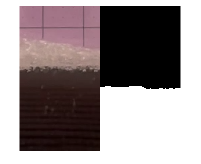

    
%     props = bwpropfilt(BW,)
% end
montage({frame,BW})

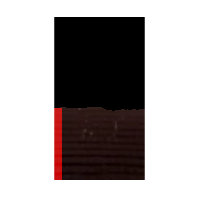


lineMask = zeros(size(BW));
lineMask(end-round(heightCm/3.4*size(BW,1)):end,1:10) = 1;
lineMasks = zeros(size(maskedImage));
lineMasks(:,:,1) = lineMask;
maskedImage(lineMasks==1) = 200;
% montage({BW,maskedImage})
imshow(maskedImage)


% Q4
nnz(BW)/size(BW,1)/size(BW,2) % 47 percent

ans = 0.4394

function heightCm = solveHeight(BW)
    imageSize = size(BW,1)*size(BW,2);
    height = 3.4;
%     width = height/size(BW,1)*size(BW,2);
    areaPropotion = regionprops("table",BW,"Area").Area / imageSize;
    heightCm = areaPropotion * height;
end